# **INICIALIZACAO**

clear all
close all
clc
init

# **AUTOVALORES**

eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339


# **CONTROLABILIDADE**

rank(ctrb(A,B))

ans = 4

# **POLE PLACEMENT**

P = [-1.0, -1.1, -1.2, -1.3];
K = place(A,B,P)

K =    -1.7160   -7.0260  142.5320   58.0520


# **LQR**

Q = diag([10,1,10,10]);
R = 0.001;
K = lqr(A,B,Q,R)

K = 	1.0e+03 *

   -0.1000   -0.1426    1.0125    0.4571


eig(A-B*K)

ans =  -12.0769 + 0.0000i
  -1.8188 + 1.2742i
  -1.8188 - 1.2742i
  -1.6791 + 0.0000i


# **Simulação**

x = $\left[\matrix{x & \dot{x} & \theta & \dot{\theta}} \right]^T$

tspan = 0:.001:15;

x0 = [-1; 0; pi+.4; 0]; % initial condition
wr = [1; 0; pi; 0]; % reference position
% u  =@(tt, xx) [tt, -K*(xx - wr)]; % control law
u  =@(tt, xx) ctrl(tt,xx,K,wr);
% [t,x] = ode45(@(t,x)pendcart(x,m,M,L,g,d,u(t,x)),tspan,x0);
[t,x] = ode45(@(t,x)pendcart(x,m,M,L,g,d,u(t,x)),tspan,x0);

# **ANIMACAO**

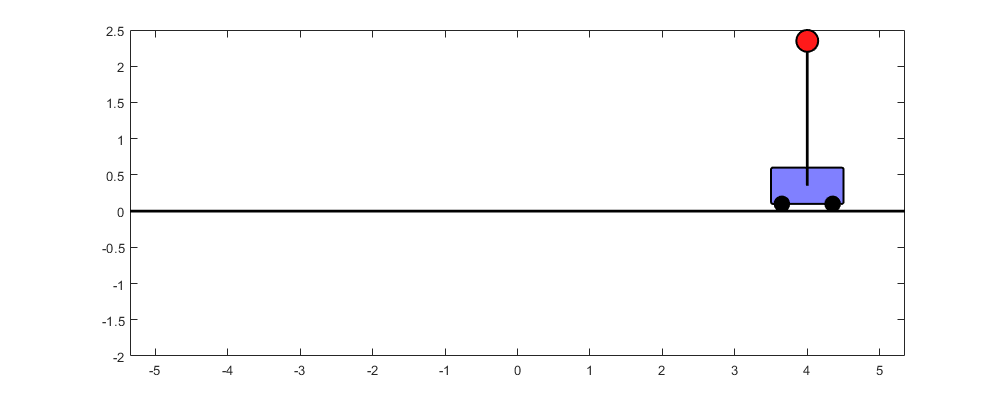

passo = 200;
animate_cart(t, x, m, M, L, passo);

# **GRAFICO ESTADOS**

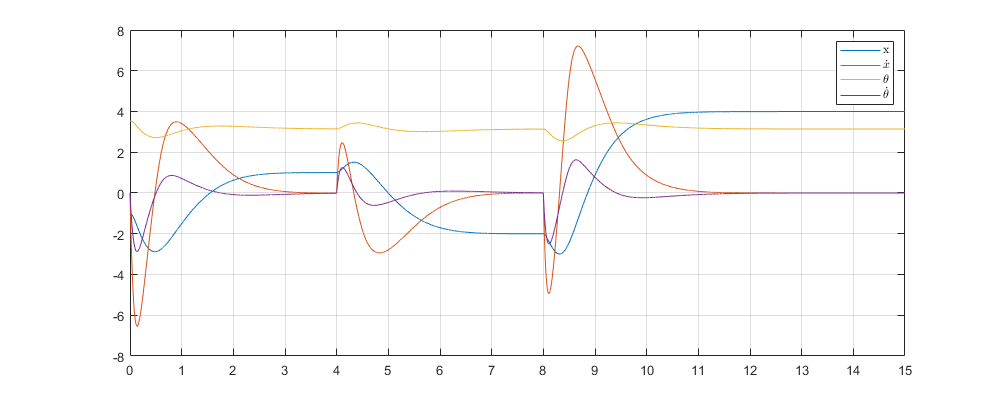

h = plot(t,x);
leg = legend('x', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(leg,'Interpreter','latex');
grid on;
h(1).Parent.XTick = [0:1:15];